clc
close all
clear all

% Load training and test data using imageDatastore.
syntheticDir = fullfile(toolboxdir('vision'),'visiondata','digits','synthetic');
handwrittenDir = fullfile(toolboxdir('vision'),'visiondata','digits','handwritten');

% |imageDatastore| recursively scans the directory tree containing the
% images. Folder names are automatically used as labels for each image.
trainingSet = imageDatastore(syntheticDir,'IncludeSubFolders',true,'LabelSource','foldernames');
testSet = imageDatastore(handwrittenDir,'IncludeSubFolders',true,'LabelSource','foldernames');

%Sacmos el 60% de las imagenes del Training de 
nFiles = length(trainingSet.Files);
RandIndices = randperm(nFiles);
nSixtyPercent = round(0.6*nFiles);
indices = RandIndices(1:nSixtyPercent);
trainingSetTrainingVerdad = subset(trainingSet, indices);
indicesVal = RandIndices(nSixtyPercent+1:end);
validationSet = subset(trainingSet, indicesVal);



% reset(trainingSet);
% while hasdata(trainingSet)
%     [data1, data2] = read(trainingSet)
%     imshow(data1)
%     % Izenburua = strcat('El digito es; ', cat2str(data2))
%     %title(Izenburua)
%     pause
% end

net = dlnetwork; %Objeto tipo network

Arquitectura = [
    imageInputLayer([16 16 3],"Name","imageinput")
    convolution2dLayer([3 3],64,"Name","conv","Padding","same")
    reluLayer("Name","relu1")
    maxPooling2dLayer([2 2],"Name","maxpool_1","Padding","same","Stride",[2 2])
    convolution2dLayer([8 8],32,"Name","conv2","Padding","same")
    reluLayer("Name","relu2")
    maxPooling2dLayer([2 2],"Name","maxpool","Padding","same","Stride",[2 2])
    fullyConnectedLayer(50,"Name","fc1")
    reluLayer("Name","relu3")
    fullyConnectedLayer(10,"Name","fc2")
    softmaxLayer("Name","softmax")];
net = addLayers(net,Arquitectura);

% clean up helper variable
clear Arquitectura;

net = initialize(net);

plot (net)


OpcionesEntrenamiento = trainingOptions("sgdm", ...
    LearnRateSchedule = "piecewise", ...
    LearnRateDropFactor = 0.99, ...
    LearnRateDropPeriod = 10, ...
    InitialLearnRate = 1e-6,...
    MaxEpochs = 100, ...
    MiniBatchSize = 16, ... 
    Plots = "training-progress",...
    Momentum = 0.95,...
    ValidationData = validationSet,... %Lo nuevo metido de lo que pide
    validationFrequency = 10,...
    validationPatience = inf, ...
    shuffle = "every-epoch")

OpcionesEntrenamiento =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9500
                InitialLearnRate: 1.0000e-06
                       MaxEpochs: 100
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.9900
             LearnRateDropPeriod: 10
                   MiniBatchSize: 16
                         Shuffle: 'every-epoch'
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
        PreprocessingEnvironment: 'serial'
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.ImageDatastore]
             ValidationFrequency: 10
              ValidationPatience: Inf
 

net = trainnet(trainingSet, net,"crossentropy",OpcionesEntrenamiento);

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss
    _________    _____    ___________    _________    ____________    ______________
            0        0       00:00:15        1e-06                            13.965
            1        1       00:00:16        1e-06           13.95                  
           10        1       00:00:28        1e-06          13.367            12.467
           20        1       00:00:30        1e-06          9.0456            9.1184
           30        1       00:00:31        1e-06          5.1207            5.9572
           40        1       00:00:32        1e-06          6.0533            5.1913
           50        1       00:00:34        1e-06          2.4488            3.6072
           60        1       00:00:35        1e-06          2.8111            2.2139
           70        2       00:00:36        1e-06          2.8698            2.0001
           80        2       00:00:37        1e-06          1.559

data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   252   255   255   255   255   255
   255   255   255   255   255   255   255   255   253   163    87   149   250   255   255   255
   255   255   255   255   255   255   255   255   112   135   237   127   159   255   255   255
   255   255   255   255   255   255   255   193    71   198   244   229   128   255   255   255
   255   255   255   255   255   255   221   100   219   255   255   240   140   255   255   255
   255   255   255   255   255   255    93   195   255   255   255   242   114   254   255   255
   255   255   255   255   255   192   113   255   255   255   255   223   127   255   255   255
   255   255   255   255   255    99   181   255   255   255   255   182   170   255   255   255
   255   255   255   255   255    97   217   255   255   255   255   137   224   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\0\digit_0_1.png'
    FileSize: 349
       Label: 0


Porbmas = single
0.7277

refmax = 8

ans = categorical
     0 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   244   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   187   177   255   255   255   255
   255   255   255   255   255   255   255   255   255   197   125   255   255   255   255   255
   255   255   255   255   255   255   239   229   252   112   224   255   255   255   255   255
   255   255   255   255   255   217   172   226   110   111   255   255   255   255   255   255
   255   255   255   255   249   142   246   253   100   142   146   250   255   255   255   255
   255   255   255   255   200   171   255   202   133   255   196   172   255   255   255   255
   255   255   255   255   156   206   255   117   215   255   240   139   255   255   255   255
   255   255   255   255   114   226   207   118   255   255   189   160   255   255   255   255
   255   255   255   255   128   225   120   198   255   208   117   239   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\0\digit_0_10.png'
    FileSize: 391
       Label: 0


Porbmas = single
0.5851

refmax = 4

ans = categorical
     0 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   254   240   227   248   255   255   255   255   255   255
   255   255   255   255   255   241   106    80   106    85   148   255   255   255   255   255
   255   255   255   255   245   106   175   249   254   241   111   144   255   255   255   255
   255   255   255   255   166   157   255   255   255   255   249    94   229   255   255   255
   255   255   255   255   148   243   255   255   255   255   255   156   187   255   255   255
   255   255   255   241   144   255   255   255   255   255   255   157   170   255   255   255
   255   255   255   240   140   255   255   255   255   255   255   137   217   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\0\digit_0_11.png'
    FileSize: 358
       Label: 0


Porbmas = single
0.9219

refmax = 8

ans = categorical
     0 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   251   220   209   219   254   255   255   255
   255   255   255   255   255   255   231   129    77    85   104    66   129   255   255   255
   255   255   255   255   255   216    74   146   229   253   255   251   105   197   255   255
   255   255   255   255   203    34   181   255   255   255   255   255   184   158   255   255
   255   255   255   255   144    97   254   255   255   255   255   255   178   159   255   255
   255   255   255   255   110   204   255   255   255   255   255   255   119   185   255   255
   255   255   255   224    99   255   255   255   255   255   255   195    79   249   255   255
   255   255   255   171   154   255   255   255   255   255   207    57   214   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\0\digit_0_12.png'
    FileSize: 376
       Label: 0


Porbmas = single
0.9971

refmax = 1

ans = categorical
     0 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   253   179   135   204   255   255   255   255   255   255   255
   255   255   255   255   255   168   169   212   128   155   255   255   255   255   255   255
   255   255   255   255   224   155   255   255   254   153   195   255   255   255   255   255
   255   255   255   255   191    99   255   255   255   243   136   250   255   255   255   255
   255   255   255   255   117   185   255   255   255   255   161   212   255   255   255   255
   255   255   255   226    94   255   255   255   255   255   174   205   255   255   255   255
   255   255   255   181   147   255   255   255   255   255   130   232   255   255   255   255
   255   255   255   134   201   255   255   255   255   209   116   255   255   255   255   255
   255   255   255   124   224   255   255   255   255   134   215   255   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\0\digit_0_2.png'
    FileSize: 369
       Label: 0


Porbmas = single
0.8869

refmax = 8

ans = categorical
     0 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   247   245   254   255   255   255   255   255
   255   255   255   255   255   255   255   164    87    83   120   231   255   255   255   255
   255   255   255   255   255   255   159    88   216   250   184    90   243   255   255   255
   255   255   255   255   255   223    53   232   255   255   255   185   166   255   255   255
   255   255   255   255   255   149   135   255   255   255   255   237   137   255   255   255
   255   255   255   255   243    82   232   255   255   255   255   240   140   255   255   255
   255   255   255   255   173   152   255   255   255   255   255   229   136   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\0\digit_0_3.png'
    FileSize: 384
       Label: 0


Porbmas = single
0.9915

refmax = 8

ans = categorical
     0 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   253   178   140   180   252   255   255   255   255   255
   255   255   255   255   255   255   123   121   164    92   123   255   255   255   255   255
   255   255   255   255   255   195    83   251   255   255    96   212   255   255   255   255
   255   255   255   255   255   138   160   255   255   255   154   185   255   255   255   255
   255   255   255   255   255   125   166   255   255   255   133   168   255   255   255   255
   255   255   255   255   255   159   116   255   255   207    71   240   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\0\digit_0_4.png'
    FileSize: 277
       Label: 0


Porbmas = single
0.4788

refmax = 8

ans = categorical
     0 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   253   251   249   255   255   255   255   255
   255   255   255   255   255   255   255   140    59   100    92   123   185   255   255   255
   255   255   255   255   255   245    92    38   148   193   251   228   121   159   255   255
   255   255   255   255   255   124    98   221   255   249   255   255   255   133   189   255
   255   255   255   255   217    68   245   255   255   255   255   255   255   220   120   255
   255   255   255   255   160   131   255   255   255   255   255   255   255   235   114   255
   255   255   255   255   146   159   255   255   255   255   255   255   255   212   146   255
   255   255   255   255   146   159   255   255   255   255   255   255   255   12

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\0\digit_0_5.png'
    FileSize: 376
       Label: 0


Porbmas = single
0.6930

refmax = 8

ans = categorical
     0 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   252   241   241   205   227   255   255   255   255   255
   255   255   255   255   255   255   175   125   122   121   100   155   255   255   255   255
   255   255   255   255   255   196    66   177   255   255   250   106   229   255   255   255
   255   255   255   255   247   121   237   255   255   255   255   163   206   255   255   255
   255   255   255   255   177   136   255   255   255   255   255   141   208   255   255   255
   255   255   255   255   139   200   255   255   255   255   240    98   246   255   255   255
   255   255   255   255   124   184   255   255   255   255   131   156   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\0\digit_0_6.png'
    FileSize: 335
       Label: 0


Porbmas = single
0.6209

refmax = 9

ans = categorical
     0 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   242   239   255   112   171   255   255   255   255   255
   255   255   255   255   195   107    42    60   112    62   246   255   255   255   255   255
   255   255   234   119    97    65   149   236    90    98   155   255   255   255   255   255
   255   205    91   168   166   123   255   160   126   255    98   209   255   255   255   255
   204    64   214   255   108   243   225    69   234   255   201   137   255   255   255   255
    53   209   255   255   185   255   103   172   255   255   226   118   255   255   255   255
   191   255   255   255   255   191    90   255   255   255   184   124   255   255   255   255
   255   255   255   255   250    76   205   255   255   255    97   215   255   255   255   255
   255   255   255   255   142   106   255   255   255   129   129   255   255   255   255   255
   255   255   255   230    79   233   255   250   132   118   254   255   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\0\digit_0_7.png'
    FileSize: 489
       Label: 0


Porbmas = single
0.9997

refmax = 8

ans = categorical
     0 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   239   153   115   144   241   255   255   255   255   255   255
   255   255   255   255   231   108   188   223   196   127   250   255   255   255   255   255
   255   255   255   255   116   178   255   255   255   137   175   255   255   255   255   255
   255   255   255   246    79   238   255   255   255   169   141   255   255   255   255   255
   255   255   255   249    87   238   255   255   255   184   146   255   255   255   255   255
   255   255   255   255   112   213   255   255   255   172   183   255   255   255   255   255
   255   255   255   255   138   205   255   255   255   126   215   255   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\0\digit_0_8.png'
    FileSize: 321
       Label: 0


Porbmas = single
0.7806

refmax = 8

ans = categorical
     0 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   254   249   165   212   255   255   255   255   255
   255   255   255   255   255   255   181   105   216   127    72   183   255   255   255   255
   255   255   255   255   255   167    85   213   255   255   231    94   247   255   255   255
   255   255   255   255   200    76   243   255   255   255   255   107   207   255   255   255
   255   255   255   255   103   181   255   255   255   255   255   118   223   255   255   255
   255   255   255   247    68   230   255   255   255   255   227   107   254   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\0\digit_0_9.png'
    FileSize: 306
       Label: 0


Porbmas = single
0.6745

refmax = 4

ans = categorical
     0 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   230   236   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   146   158   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   187   119   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   194   120   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   194   109   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   194   119   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   195    92   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   199    73   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   216    82   255   255   255   255   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\1\digit_1_1.png'
    FileSize: 184
       Label: 1


Porbmas = single
0.8059

refmax = 8

ans = categorical
     1 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   235   210   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   115   149   255   255   255   255   255   255   255
   255   255   255   255   255   255   176    43   189   255   255   255   255   255   255   255
   255   255   255   255   255   187   203   132   182   255   255   255   255   255   255   255
   255   255   255   255   255   248   255   131   181   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   152   184   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   180   181   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   197   141   255   255   255   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\1\digit_1_10.png'
    FileSize: 292
       Label: 1


Porbmas = single
0.9592

refmax = 2

ans = categorical
     1 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   249   180   254   255   255   255   255   255   255   255
   255   255   255   255   255   255   236    91   254   255   255   255   255   255   255   255
   255   255   255   255   255   255   243    65   234   255   255   255   255   255   255   255
   255   255   255   255   255   255   255    95   216   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   126   181   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   130   161   255   255   255   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\1\digit_1_11.png'
    FileSize: 196
       Label: 1


Porbmas = single
0.7849

refmax = 5

ans = categorical
     1 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   234   227   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   168   143   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   165   143   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   158   142   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   136   179   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   120   194   255   255   255   255   255   255
   255   255   255   255   255   255   255   255    91   201   255   255   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\1\digit_1_12.png'
    FileSize: 189
       Label: 1


Porbmas = single
0.5444

refmax = 8

ans = categorical
     1 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   230   197   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   122   175   255   255   255   255   255   255
   255   255   255   255   255   255   255   237   104   253   255   255   255   255   255   255
   255   255   255   255   255   255   255   207   136   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   159   168   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   141   199   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   131   219   255   255   255   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\1\digit_1_2.png'
    FileSize: 213
       Label: 1


Porbmas = single
0.9154

refmax = 8

ans = categorical
     1 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   249   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   223   120   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   156   129   255   255   255   255   255   255   255
   255   255   255   255   255   255   200    39   186   255   255   255   255   255   255   255
   255   255   255   255   255   177   122   111   184   255   255   255   255   255   255   255
   255   255   255   255   140   116   255   128   199   255   255   255   255   255   255   255
   255   255   255   254   213   249   255   132   187   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   131   181   255   255   255   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\1\digit_1_3.png'
    FileSize: 272
       Label: 1


Porbmas = single
0.5605

refmax = 2

ans = categorical
     1 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   234   247   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   113   150   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   185    85   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   230    87   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   235    92   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   205   100   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   196   155   255   255   255   255   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\1\digit_1_4.png'
    FileSize: 181
       Label: 1


Porbmas = single
0.8361

refmax = 8

ans = categorical
     1 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   253   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   254   108   230   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   114   183   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   141   137   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   183   118   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   194   120   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   195   103   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   204    71   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   231    88   255   255   255   255   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\1\digit_1_5.png'
    FileSize: 210
       Label: 1


Porbmas = single
0.8952

refmax = 8

ans = categorical
     1 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   253   254   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   115   220   255   255   255   255   255   255   255
   255   255   255   255   255   255   214    67   249   255   255   255   255   255   255   255
   255   255   255   255   255   255    86   144   255   255   255   255   255   255   255   255
   255   255   255   255   255   165    41   231   255   255   255   255   255   255   255   255
   255   255   255   255   176    94    96   253   255   255   255   255   255   255   255   255
   255   255   255   215   100   180   109   255   255   255   255   255   255   255   255   255
   255   255   255   225   235   158   141   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   111   156   255   255   255   255   255   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\1\digit_1_6.png'
    FileSize: 258
       Label: 1


Porbmas = single
0.9999

refmax = 8

ans = categorical
     1 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   250   253   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   141   234   255   255   255   255   255   255
   255   255   255   255   255   255   255   253    99   239   255   255   255   255   255   255
   255   255   255   255   255   255   255   226   104   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   179   134   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   133   179   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   117   200   255   255   255   255   255   255   255
   255   255   255   255   255   255   254    84   228   255   255   255   255   255   255   255
   255   255   255   255   255   255   238    71   244   255   255   255   255   255   255   255
   255   255   255   255   255   255   221    90   255   255   255   255   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\1\digit_1_7.png'
    FileSize: 240
       Label: 1


Porbmas = single
0.6353

refmax = 8

ans = categorical
     1 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   230   243   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   156   214   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   125   220   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   115   210   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   115   206   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   121   206   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   110   206   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   110   206   255   255   255   255   255   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\1\digit_1_8.png'
    FileSize: 207
       Label: 1


Porbmas = single
0.9828

refmax = 8

ans = categorical
     1 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   178   194   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   109   181   255   255   255   255   255   255
   255   255   255   255   255   255   255   255    83   222   255   255   255   255   255   255
   255   255   255   255   255   255   255   237    73   243   255   255   255   255   255   255
   255   255   255   255   255   255   255   204    83   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   181   119   255   255   255   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\1\digit_1_9.png'
    FileSize: 186
       Label: 1


Porbmas = single
0.7737

refmax = 5

ans = categorical
     1 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   240   137   146   224   255   255   255   255   255   255   255
   255   255   255   255   255   155   113   133    55   200   255   255   255   255   255   255
   255   255   255   255   254   122   246   255   201    74   249   255   255   255   255   255
   255   255   255   255   255   166   184   249   255    80   194   255   255   255   255   255
   255   255   255   255   255   246   205   237   255    80   194   255   255   255   255   255
   255   255   255   255   255   255   255   255   219    59   243   255   250   255   255   255
   255   255   255   255   255   255   255   255    94   154   255   252   241   255   255   255
   255   255   255   255   255   255   255   137   117   255   255   255   255   255   255   255
   255   255   255   255   255   255   180    97   241   255   255   255   255   255   255   255
   255   255   255   255   255   180    77   242   255   255   255   255   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\2\digit_2_1.png'
    FileSize: 383
       Label: 2


Porbmas = single
0.5755

refmax = 8

ans = categorical
     2 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   224   223   255   255   255   255   255   255
   255   255   255   255   255   255   216   101    64    97   246   255   255   255   255   255
   255   255   255   255   255   163    62   175   228    87   240   255   255   255   255   255
   255   255   255   251    98    85   230   255   113   141   255   255   255   255   255   255
   255   255   255   167   130   252   255   185    81   252   255   255   255   255   255   255
   255   255   255   244   246   255   237    78   224   255   255   255   255   255   255   255
   255   255   255   255   255   255    96   162   255   255   255   255   255   255   255   255
   255   255   255   255   255   183   101   255   255   255   255   255   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\2\digit_2_10.png'
    FileSize: 376
       Label: 2


Porbmas = single
0.4478

refmax = 2

ans = categorical
     2 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   250   234   241   255   255   255   255   255   255   255   255
   255   255   255   255   255   222    63    69   207   255   255   255   255   255   255   255
   255   255   255   255   255   252   245   201    87   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   100   229   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   140   208   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   143   208   255   255   255   255   255   255
   255   255   255   255   255   252   247   255   103   226   255   255   255   255   255   255
   255   255   255   255   234    96    60   102    92   252   255   255   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\2\digit_2_11.png'
    FileSize: 328
       Label: 2


Porbmas = single
0.4584

refmax = 4

ans = categorical
     2 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   245   233   180   163   204   255   255   255   255   255   255   255   255
   255   251   141    39    33    72    93    25   189   255   255   255   255   255   255   255
   255   232   100   199   223   254   255   160   108   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   171   107   255   255   255   255   255   255   255
   255   255   255   255   255   255   255    97   171   255   255   255   255   255   255   255
   255   255   255   255   255   255   163    72   250   255   255   255   255   255   255   255
   255   255   255   255   255   208    51   218   255   255   255   255   255   255   255   255
   255   255   255   255   208    55   198   255   255   255   255   255   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\2\digit_2_12.png'
    FileSize: 389
       Label: 2


Porbmas = single
0.9698

refmax = 2

ans = categorical
     2 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   248   249   255   255   255   255   255
   255   255   255   255   255   255   231   161   100    80   106   249   255   255   255   255
   255   255   255   255   200   106    71   117   185   238    99   222   255   255   255   255
   255   255   233    79    67   174   245   255   255   219    81   248   255   255   255   255
   255   255   243   194   245   255   255   255   255   100   165   255   255   255   255   255
   255   255   255   255   255   255   255   255   188    90   255   255   255   255   255   255
   255   255   255   255   255   255   255   220    61   222   255   255   255   255   255   255
   255   255   255   255   255   255   247    84   188   255   255   255   255   255   255   255
   255   255   255   255   255   255   121   121   255   255   255   255   255   255   255   255
   255   255   255   255   255   185    61   246   255   255   255   255   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\2\digit_2_2.png'
    FileSize: 400
       Label: 2


Porbmas = single
0.6620

refmax = 8

ans = categorical
     2 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   225   149   116   162   247   255   255   255   255   255   255
   255   255   255   255   163    69   146   183   117    96   243   255   255   255   255   255
   255   255   255   226    67   232   255   255   255   131   139   255   255   255   255   255
   255   255   255   163   162   255   255   255   255   217    78   255   255   255   255   255
   255   255   255   138   203   255   255   255   255   198    88   255   255   255   255   255
   255   255   255   211   215   255   255   255   255    98   184   255   255   255   255   255
   255   255   255   221   189   255   255   255   149   111   255   255   255   255   255   255
   255   255   255   252   241   255   255   176    74   246   255   255   255   255   255   255
   255   255   255   255   255   255   178    60   223   255   255   255   255   255   255   255
   255   255   255   255   255   178    60   224   255   255   255   255   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\2\digit_2_3.png'
    FileSize: 387
       Label: 2


Porbmas = single
0.4139

refmax = 8

ans = categorical
     2 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   254   220   188   146   195   255   255   255   255   255   255   255
   255   255   255   227    93    35    72    73    49   130   255   255   255   255   255   255
   255   255   242    59   154   239   254   255   196    73   255   255   255   255   255   255
   255   255   248   156   243   255   255   255   144    91   255   255   255   255   255   255
   255   255   255   255   255   255   255   215    37   213   255   255   255   255   255   255
   255   255   255   255   255   255   225    65   188   255   255   255   255   255   255   255
   255   255   255   255   255   232    48   136   175   148    96    93    89   13

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\2\digit_2_4.png'
    FileSize: 326
       Label: 2


Porbmas = single
0.6345

refmax = 4

ans = categorical
     2 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   243   205   190   235   255   255   255   255   255   255   255   255   255
   255   255   202    73    59    35    56   112   247   255   255   255   255   255   255   255
   255   237    67   193   119   131   245    70   123   255   255   255   255   255   255   255
   255   233    75    72    78   231   255   173    93   255   255   255   255   255   255   255
   255   255   248   243   251   255   255   167   107   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   100   156   255   255   255   255   255   255   255
   255   255   255   255   255   255   221    56   235   255   255   255   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\2\digit_2_5.png'
    FileSize: 423
       Label: 2


Porbmas = single
0.5575

refmax = 6

ans = categorical
     2 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   251   144   109   232   255   255   255   255   255   255   255
   255   255   255   255   235    94   152   118   128   255   255   255   255   255   255   255
   255   255   255   255   173   183   255   169   107   255   255   255   255   255   255   255
   255   255   255   255   251   254   255   110   155   255   255   255   255   255   255   255
   255   255   255   255   255   255   255    93   194   255   255   255   255   255   255   255
   255   255   255   255   255   255   240    71   238   255   255   255   255   255   255   255
   255   255   255   255   255   255   195   107   255   255   255   255   255   255   255   255
   255   255   255   255   255   248    87   206   255   255   255   255   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\2\digit_2_6.png'
    FileSize: 299
       Label: 2


Porbmas = single
0.5331

refmax = 3

ans = categorical
     2 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   241   178   101   179   255   255   255   255
   255   255   255   255   255   253   201   126    74   109   118    88   255   255   255   255
   255   255   255   232    92    76    67   150   242   255    99   168   255   255   255   255
   255   255   255   253   209   212   252   255   255   158    85   254   255   255   255   255
   255   255   255   255   255   255   255   255   203    48   229   255   255   255   255   255
   255   255   255   255   255   255   255   206    55   199   255   255   255   255   255   255
   255   255   255   255   255   255   206    84   205   255   255   255   255   255   255   255
   255   255   255   255   255   177    57   202   255   255   255   255   255   255   255   255
   255   255   255   255   158    67   223   255   255   255   255   255   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\2\digit_2_7.png'
    FileSize: 416
       Label: 2


Porbmas = single
0.9931

refmax = 8

ans = categorical
     2 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   251   219   187   240   255   255   255   255   255   255   255   255
   255   255   255   236    78   103    97    62   208   255   255   255   255   255   255   255
   255   255   255   117   152   255   255   163    97   255   255   255   255   255   255   255
   255   255   243    70   234   255   255   212   103   255   255   255   255   255   255   255
   255   255   255   159   181   255   255   173   116   255   255   255   255   255   255   255
   255   255   255   254   246   255   255   121   186   255   255   255   255   255   255   255
   255   255   255   255   255   255   231    86   244   255   255   255   255   255   255   255
   255   255   255   255   255   255   138   175   255   255   255   255   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\2\digit_2_8.png'
    FileSize: 388
       Label: 2


Porbmas = single
0.9999

refmax = 8

ans = categorical
     2 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   246   184    93   133   251   255   255   255   255   255   255
   255   255   255   255   245    83    63   145    74   122   255   255   255   255   255   255
   255   255   255   255    92   135   255   255   204    67   253   255   255   255   255   255
   255   255   255   251   197   253   255   255   244    67   240   255   255   255   255   255
   255   255   255   255   255   255   255   255   244    70   241   255   255   255   255   255
   255   255   255   255   255   255   255   255   222    88   254   255   255   255   255   255
   255   255   255   255   255   255   255   255   156   106   255   255   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\2\digit_2_9.png'
    FileSize: 350
       Label: 2


Porbmas = single
0.9155

refmax = 4

ans = categorical
     2 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   248   227   221   218   250   255   255   255   255   255   255   255   255
   255   255   242    99    85   115    89    87   243   255   255   255   255   255   255   255
   255   255   252   236   255   255   255    87   183   255   255   255   255   255   255   255
   255   255   255   255   255   255   246    77   223   255   255   255   255   255   255   255
   255   255   255   255   255   250    96   143   255   255   255   255   255   255   255   255
   255   255   255   255   253   122   149   254   255   255   255   255   255   255   255   255
   255   255   255   255   225   113   183   121   168   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   251    90   177   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   116   131   255   255   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\3\digit_3_1.png'
    FileSize: 350
       Label: 3


Porbmas = single
0.8697

refmax = 8

ans = categorical
     3 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   244   135   129   121   119   145   247   255   255   255   255   255   255   255
   255   255   252   151   145   181   190   107   191   255   255   255   255   255   255   255
   255   255   255   255   255   255   166   114   247   255   255   255   255   255   255   255
   255   255   255   255   241   118   117   248   255   255   255   255   255   255   255   255
   255   255   255   255   160    53   197   230   248   255   255   255   255   255   255   255
   255   255   255   255   255   186   110    85    87   132   230   255   255   255   255   255
   255   255   255   255   255   255   255   255   233   161    94   225   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\3\digit_3_10.png'
    FileSize: 324
       Label: 3


Porbmas = single
0.9819

refmax = 4

ans = categorical
     3 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   245   100    77   106   234   255   255   255   255   255   255
   255   255   255   255   255   247   210   227   157   102   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255    88   229   255   255   255   255   255
   255   255   255   255   255   255   255   255   170   111   253   255   255   255   255   255
   255   255   255   255   255   249   189   104   120   244   255   255   255   255   255   255
   255   255   255   255   255   223    68    40   148   253   255   255   255   255   255   255
   255   255   255   255   255   255   255   242    77   184   255   255   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\3\digit_3_11.png'
    FileSize: 298
       Label: 3


Porbmas = single
0.9296

refmax = 10

ans = categorical
     3 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   240   184   163   176   184   232   255   255   255   255   255   255   255
   255   255   247    70    70   123   122    77    72    72   221   255   255   255   255   255
   255   255   202   127   255   255   226   172    73    89   233   255   255   255   255   255
   255   255   223   230   255   254    61   105   215   255   255   255   255   255   255   255
   255   255   255   255   255   255   162    62   234   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   142    57   243   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   140   107   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   254    95   201   255   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\3\digit_3_12.png'
    FileSize: 369
       Label: 3


Porbmas = single
0.3586

refmax = 5

ans = categorical
     3 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   254   220   180   138   120   120   167   241   255   255   255   255   255   255
   255   255   215    52   133   182   178   180   125    79   231   255   255   255   255   255
   255   255   252   239   255   255   255   255   218    69   211   255   255   255   255   255
   255   255   255   255   255   255   247   149   103   219   255   255   255   255   255   255
   255   255   255   255   255   195    91   134   249   255   255   255   255   255   255   255
   255   255   255   255   255   129    95   147   186   236   255   255   255   255   255   255
   255   255   255   255   255   255   223   170   144    94   146   248   255   255   255   255
   255   255   255   255   255   255   255   255   255   251   163   137   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\3\digit_3_2.png'
    FileSize: 387
       Label: 3


Porbmas = single
0.6361

refmax = 8

ans = categorical
     3 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   232   168   120   117   197   255   255   255   255   255   255
   255   255   255   230   129    95   155   181   174    81   224   255   255   255   255   255
   255   255   244   107   185   252   255   255   255   124   214   255   255   255   255   255
   255   255   226   141   255   255   255   255   182   120   255   255   255   255   255   255
   255   255   253   241   255   255   255   168   129   250   255   255   255   255   255   255
   255   255   255   255   255   255   132    43   107   137   231   255   255   255   255   255
   255   255   255   255   255   255   223   232   217   154    84   242   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   164   185   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   137   183   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\3\digit_3_3.png'
    FileSize: 400
       Label: 3


Porbmas = single
0.7516

refmax = 1

ans = categorical
     3 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   250   224   184   182   235   255   255   255   255   255   255
   255   255   255   255   201    73    70    64    93    72   244   255   255   255   255   255
   255   255   255   255    91   182   253   255   209    67   244   255   255   255   255   255
   255   255   255   255   222   242   255   197    68   192   255   255   255   255   255   255
   255   255   255   255   255   248   140    86   220   255   255   255   255   255   255   255
   255   255   255   255   255   180    34    79    88   103   171   255   255   255   255   255
   255   255   255   255   255   254   245   229   225   184    45   207   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\3\digit_3_4.png'
    FileSize: 351
       Label: 3


Porbmas = single
0.9472

refmax = 4

ans = categorical
     3 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   227   170   120   123   227   255   255   255   255   255   255   255
   255   255   255   157    80    34   173   123    76   254   255   255   255   255   255   255
   255   255   255    96    60   161   255   255    93   196   255   255   255   255   255   255
   255   255   255   244   236   255   255   226    70   232   255   255   255   255   255   255
   255   255   255   255   255   255   202    62   172   255   255   255   255   255   255   255
   255   255   255   255   255   178    22    48   161   249   255   255   255   255   255   255
   255   255   255   255   255   219   193   186    77   128   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   168    66   255   255   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\3\digit_3_5.png'
    FileSize: 326
       Label: 3


Porbmas = single
0.5350

refmax = 5

ans = categorical
     3 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   206   132   204   255   255   255   255   255
   255   255   255   255   255   255   241   119   107   155    95   255   255   255   255   255
   255   255   255   255   255   255   118   181   255   216    94   255   255   255   255   255
   255   255   255   255   255   251   226   255   255   114   190   255   255   255   255   255
   255   255   255   255   255   255   255   255   159   128   255   255   255   255   255   255
   255   255   255   255   255   255   255   199    28    71   217   255   255   255   255   255
   255   255   255   255   255   255   255   210   207   100   181   255   255   255   255   255
   255   255   255   255   255   255   255   255   195    73   243   255   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\3\digit_3_6.png'
    FileSize: 278
       Label: 3


Porbmas = single
0.7980

refmax = 8

ans = categorical
     3 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   250   255   255   255   255   255
   255   255   255   255   249   223   183   137   116    72    81   248   255   255   255   255
   251   140   119    95    72    84   118   172   169    37   158   255   255   255   255   255
   251   137   144   185   227   254   255   203    74   188   255   255   255   255   255   255
   255   255   255   255   255   255   174    56   190   255   255   255   255   255   255   255
   255   255   255   255   255   146    75   231   255   255   255   255   255   255   255   255
   255   255   255   250   113    91   202   171   145   177   217   254   255   255   255   255
   255   255   255   144    17    84   105   139   151   122    94    84   197   255   255   255
   255   255   255   218   197   243   255   255   255   255   255   200    77   225   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   122   17

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\3\digit_3_7.png'
    FileSize: 468
       Label: 3


Porbmas = single
0.8908

refmax = 8

ans = categorical
     3 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   230   175   232   255   255   255   255   255   255   255   255   255
   255   255   255   248    96    97    95   255   255   255   255   255   255   255   255   255
   255   255   255   150   148   255    99   236   255   255   255   255   255   255   255   255
   255   255   255    94   228   225    96   255   255   255   255   255   255   255   255   255
   255   255   255    99   190   152   153   255   255   255   255   255   255   255   255   255
   255   255   255   240   215    73   162   183   230   255   255   255   255   255   255   255
   255   255   255   255   242   143   122   114    86   151   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   249    94   161   255   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\3\digit_3_8.png'
    FileSize: 320
       Label: 3


Porbmas = single
0.9995

refmax = 7

ans = categorical
     3 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   203   100    77   215   255   255   255   255   255   255
   255   255   255   255   250   139    94   199   101   190   255   255   255   255   255   255
   255   255   255   255   190   103   255   222    72   245   255   255   255   255   255   255
   255   255   255   255   249   249   255   111   157   255   255   255   255   255   255   255
   255   255   255   255   255   255   232    60   229   255   255   255   255   255   255   255
   255   255   255   255   255   255   253   160    81   120   233   255   255   255   255   255
   255   255   255   255   255   255   255   255   247   165    73   226   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\3\digit_3_9.png'
    FileSize: 315
       Label: 3


Porbmas = single
0.8382

refmax = 5

ans = categorical
     3 


data1 = 16×16×3 uint8 array
data1(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   251   205   255   255   198   217   255   255   255   255   255
   255   255   255   255   255   229    89   255   255    79   214   255   255   255   255   255
   255   255   255   255   255   203   104   255   234    47   234   255   255   255   255   255
   255   255   255   255   255   150   150   255   229    71   249   255   255   255   255   255
   255   255   255   255   255    86   204   255   229    66   246   255   255   255   255   255
   255   255   255   255   227    81   251   255   228    82   255   255   255   255   255   255
   255   255   255   255   181   107   233   180    93    70   255   255   255   255   255   255
   255   255   255   255   216    77    99   130   173    87   255   255   255   25

data2 = struct with fields:
    Filename: 'C:\Program Files\MATLAB\R2024b\toolbox\vision\visiondata\digits\handwritten\4\digit_4_1.png'
    FileSize: 325
       Label: 4


Porbmas = single
0.9366

refmax = 5

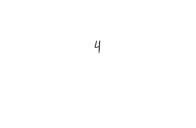


reset(testSet)
while hasdata(testSet)
    [data1, data2] = read(testSet)
    %Si da error: Prob = forward(net,double(data1))
    %forward(net,data1)
    Prob = predict(net, double(data1));
    [Porbmas, refmax] = max(Prob)
    imshow(data1)
    data2.Label
    Izenburua=strcat('El digito es: ', num2str(double(data2.Label)-1), ...
        'Ref predicha: ', num2str(refmax));
    title(Izenburua)
end

Ahora habria que dividir, con el comando partition, del datastoretrain el: datastoretrainprima y el datastrore value, y luego del training option el validationdata con el datastrore value, el validation frecuency (a 10 o 59 y el validation patiences (a infitnito)